#### **Importing preprocessed Bank Marketing csv**

bankData = readtable('BankMarketingForModelTraining.csv','PreserveVariableNames',true)

bankData = 5092×43 table
    default     housing      loan      duration     campaign     pdays     previous    poutcome     emp.var.rate    cons.conf.idx    euribor3m    nr.employed     admin.     blue-collar    entrepreneur    retired     services    student     unemployed    divorced    married     single     basic.4y    basic.6y    basic.9y    university.degree    unknown_education    cellular    telephone     Adult     Elderly      Young        <s

#### **Splitting the Data into training and testing**

cv = cvpartition(size(bankData,1),'HoldOut',0.3);
dataUpd = cv.test;
% Separate to training and test data
dataTrain = bankData(~dataUpd,:);

dataTest  = bankData(dataUpd,:);       

XTrain= dataTrain(1:end, 1:end-1)

XTrain = 3565×42 table
    default     housing      loan      duration     campaign     pdays     previous    poutcome     emp.var.rate    cons.conf.idx    euribor3m    nr.employed     admin.     blue-collar    entrepreneur    retired     services    student     unemployed    divorced    married     single     basic.4y    basic.6y    basic.9y    university.degree    unknown_education    cellular    telephone     Adult     Elderly      Young        

yTrain= dataTrain(1:end,end)

yTrain = 3565×1 table
    y
    _

    0
    0
    0
    0
    0
    0
    0
    0
    0
    0
    0
    0
    0
    0
    0
    0



XTest= dataTest(1:end, 1:end-1)

XTest = 1527×42 table
    default     housing       loan      duration    campaign     pdays     previous    poutcome     emp.var.rate    cons.conf.idx    euribor3m    nr.employed     admin.     blue-collar    entrepreneur    retired     services    student     unemployed    divorced    married     single     basic.4y    basic.6y    basic.9y    university.degree    unknown_education    cellular    telephone     Adult     Elderly      Young        

yTest= dataTest(1:end,end)

yTest = 1527×1 table
    y
    _

    0
    0
    0
    0
    0
    0
    0
    0
    0
    0
    0
    0
    0
    0
    0
    0


#### Training Model 

|=====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | NumLearningC-|  MinLeafSize | MaxNumSplits | NumVariables-|
|      | result |             | runtime     | (observed)  | ycles        |              |              | ToSample     |
|=====================================================================================================================|
|    1 | Best   |     0.12875 |      12.815 |     0.12875 |          500 |           12 |           15 |            6 |
|    2 | Best   |    0.097055 |      4.0198 |    0.097055 |           88 |            1 |         3564 |           42 |
|    3 | Accept |     0.14783 |       9.334 |    0.097055 |          324 |          338 |          233 |           42 |
|    4 | Accept |     0.11136 |      4.3416 |    0.097055 |          136 |            2 |           15 |           37 |
|    5 | Accept |     0.16858 |     0.31

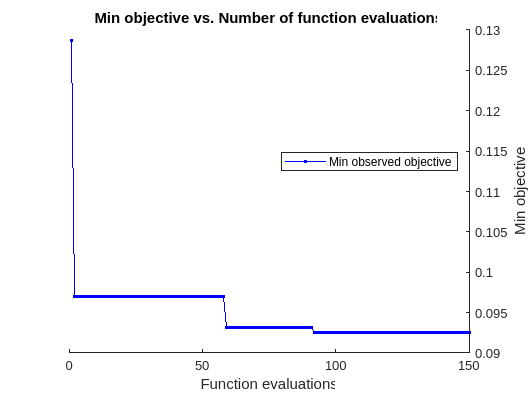


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 150 reached.
Total function evaluations: 150
Total elapsed time: 649.7563 seconds
Total objective function evaluation time: 559.7848

Best observed feasible point:
    NumLearningCycles    MinLeafSize    MaxNumSplits    NumVariablesToSample
    _________________    ___________    ____________    ____________________

           37                 5              94                  28         

Observed objective function value = 0.092567
Function evaluation time = 1.3777



finalModelRF =   ClassificationBaggedEnsemble
                       PredictorNames: {1×42 cell}
                         ResponseName: 'y'
                CategoricalPredictors: []
                           ClassNames: [0 1]
                       ScoreTransform: 'none'
                      NumObservations: 3565
    HyperparameterOptimizationResults: [150×6 table]
                           NumTrained: 37
                               Method: 'Bag'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                              FitInfo: []
                   FitInfoDescription: 'None'
                            FResample: 1
                              Replace: 1
                     UseObsForLearner: [3565×37 logical]


  

finalModelRF=fitcensemble(XTrain,yTrain,'Method','Bag','OptimizeHyperparameters', {'NumLearningCycles','MaxNumSplits','MinLeafSize','NumVariablesToSample'},'HyperparameterOptimizationOptions',struct('KFold',5,'Optimizer','gridsearch','MaxObjectiveEvaluations',150 ))

#### Saving Model

save('finalModelRF.mat','finalModelRF',"yTest","XTest")